[~,folder,~] = fileparts(pwd);
assert(strcmpi(folder,"defect reconstruction using coil and sensor array"), 'Not in project directory')
addpath('../../DCS_functions')

clear

set(groot,'defaultAxesFontName','Times New Roman')
set(groot,'defaultAxesFontSize',12)

#### Reconstruction matrix

load('precompute_30x30.mat')

lambda = 1e-7;

n = size(S,2); % number of elements
S = reshape(permute(S,[1 3 2]), [],n);
Q = eye(n);
R = (S' * S + lambda * Q) \ S';

clear n lambda S_ct

#### Perform reconstruction

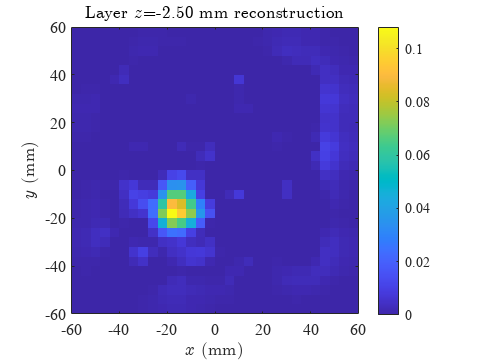

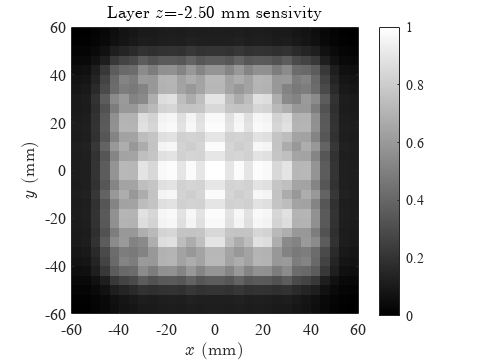

B_bar = readB('DCS_B_uniform.csv') ;%- readB('DCS_B_air.csv');
B_m   = readB('FEM_B_top-hole.txt');% - readB('FEM_B_air.txt');
delta_B = B_m - B_bar;
delta_B = reshape(delta_B, [],1);
delta_p = real(R * delta_B);

s = vecnorm(S);

layers = unique(elems_center(3,:));
for z = layers
    mask = elems_center(3,:) == z;
    x = elems_center(1,mask) * 1e3;
    y = elems_center(2,mask) * 1e3;
    n_x = length(unique(x));
    x = reshape(x, n_x, []);
    y = reshape(y, n_x, []);

    delta_p_layer = reshape(delta_p(mask), n_x, []);

    figure
    imagesc([min(x) max(x)], [min(y) max(y)], delta_p_layer.', [0 max(delta_p,[],'all')]);
    colorbar
    title(sprintf('Layer $z$=%.2f mm reconstruction', z*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
    xlim([-60 60])
    ylim([-60 60])
    axis xy square
    
    s_layer = reshape(s(mask), n_x, []) / max(s,[],'all');

    figure
    imagesc([min(x) max(x)], [min(y) max(y)], s_layer.', [0 1]);
    colormap gray
    colorbar
    title(sprintf('Layer  $z$=%.2f mm sensivity', z*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
    xlim([-60 60])
    ylim([-60 60])
    axis xy square
end


clear s layers mask n_x x y z delta_p_layer s_layer

function B = readB(filename)

data = readmatrix(fullfile('Forward_data',filename), 'CommentStyle','%');
if contains(filename, 'DCS', 'IgnoreCase',true)
    B = permute(data, [1 3 2]);
elseif contains(filename, 'FEM', 'IgnoreCase',true)
    B = data(:, 4:end);
    num_sensors = size(B,1);
    B = reshape(B, num_sensors, 3, []);
    B = pagetranspose(B);
    B = reshape(B, num_sensors*3, 1, []);
else
    error('Unknown file formatting')
end

end